# Graphical Optimizations

## 3.19


$$f(x, y)=-x+2y$$


subject to

 
$$-x^2+6x+3y \leq 27\\
18x-y^2 \geq180\\
x, y \geq 0$$


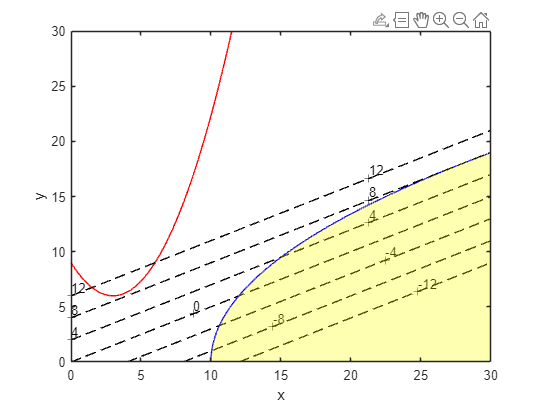

x_min = 0; y_min = 0;
x_max = 30; y_max = 30;
interval = 0.01;

[x, y] = meshgrid(x_min:interval:x_max, y_min:interval:y_max);

f = -x + 2.*y;
g1 = -x.^2 + 6.*x + 3.*y - 27;
g2 = -(y.^2) + 18.*x - 180;

figure(1);

fv = [-12, -8, -4, 0, 4, 8, 12];
contour_level = [0 0];
contour(x, y, g1, contour_level, 'r'); hold on;
contour(x, y, g2, contour_level, 'b'); hold on;
fs = contour(x, y, f, fv, 'k--'); hold on;
clabel(fs)

% Define the feasible region
feasible_region = (g1 <= 0) & (g2 >= 0) & (x >= 0) & (y >= 0);

% Create mask for the feasible region
mask = double(feasible_region);
mask(mask == 0) = NaN;

% Shade the feasible region
imagesc(x_min:interval:x_max, y_min:interval:y_max, mask, 'AlphaData', ~isnan(mask) * 0.3);
colormap([1 1 0]); hold off; % Set the colormap to yellow 

% Adjust the axis limits
xlim([x_min, x_max]);
ylim([y_min, y_max]);
xlabel('x');
ylabel('y');

there are infinite solutions of where f is minimized. 

therfore, only one optimum point exist where f is maximized.

$x^*=[28,18]$, $f(x,y) = 8.0$

## 3.45

solve the cylindrical-can design problem formulated in Section 2.2 using the graphical method.

### Desing of A Can

The purpose of this project is to design a can, shown in Fig. 2.3, to hold at 400 mL of liquid (1mL=1cm^3), as well as to meet other design requirements. The cans will be produced in the billions, so it is desirable to minimizae their manufactuing costs. Since cost can be directly related to the surface area of the sheet metal used, it is reasonable to minimize the amount of sheet metal required. Fabrication, handling, aesthetics, and shipping considerations impose the following restrictions on the size ot the can: The diameter shold be no more than 8cm and no less than 3.5cm, whereas the height should be no more than 18cm and no less than 8cm.


$$S=\pi DH+2(\frac{\pi}{4}D^2), cm^2\\
\frac{\pi}{4}D^2H\geq400 , cm^3\\
3.5\leq D\leq8, cm\\
8\leq H\leq 18, cm$$


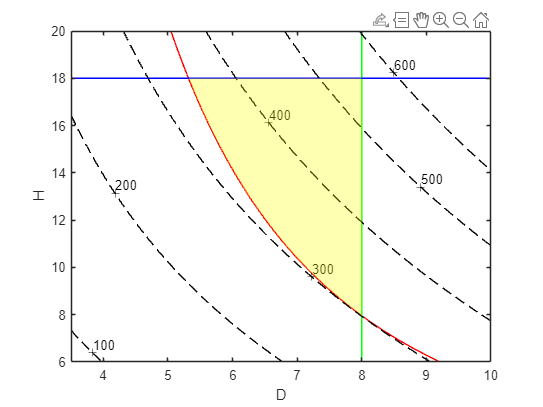

clear;

x1_min = 3.5; x1_max = 8 + 2;
x2_min = 8 - 2; x2_max = 18 + 2;
interval = 0.01;

[x1, x2] = meshgrid(x1_min:interval:x1_max, x2_min:interval:x2_max);

% the object function and the constraints
f = pi.*x1.*x2 + 2.*pi./4.*x1.^2;
g1 = pi./4.*x1.^2.*x2-400;
g2 = x1 - 8;
g3 = x2 - 18;

figure(2);

%Plot the contours of the obj function and constraints
fv = [100 200 300 400 500 600];
contour_level = [0 0];
contour(x1, x2, g1, contour_level, 'r'); hold on;
contour(x1, x2, g2, contour_level, 'g'); hold on;
contour(x1, x2, g3, contour_level, 'b'); hold on;
fs = contour(x1, x2, f, fv, 'k--'); hold on;
clabel(fs);

% Define the feasible region
feasible_region = (g1 >= 0) & (g2 <= 0) & (g3 <= 0);

% Create mask for the feasible region
mask = double(feasible_region);
mask(mask == 0) = NaN;

% Shade the feasible region
imagesc(x1_min:interval:x1_max, x2_min:interval:x2_max, mask, 'AlphaData', ~isnan(mask) * 0.3);
colormap([1 1 0]); hold off;% Set the colormap to yellow 

% Adjust the axis limits
xlim([x1_min, x1_max]);
ylim([x2_min, x2_max]);
xlabel('D'); 
ylabel('H');

The point where f is minimized is $x^*=[8, 7.96]$, the intersection of $D=8.0$ and $f(D, H)=400.0$